## Identifying a model for the gantry crane

## Generate input data

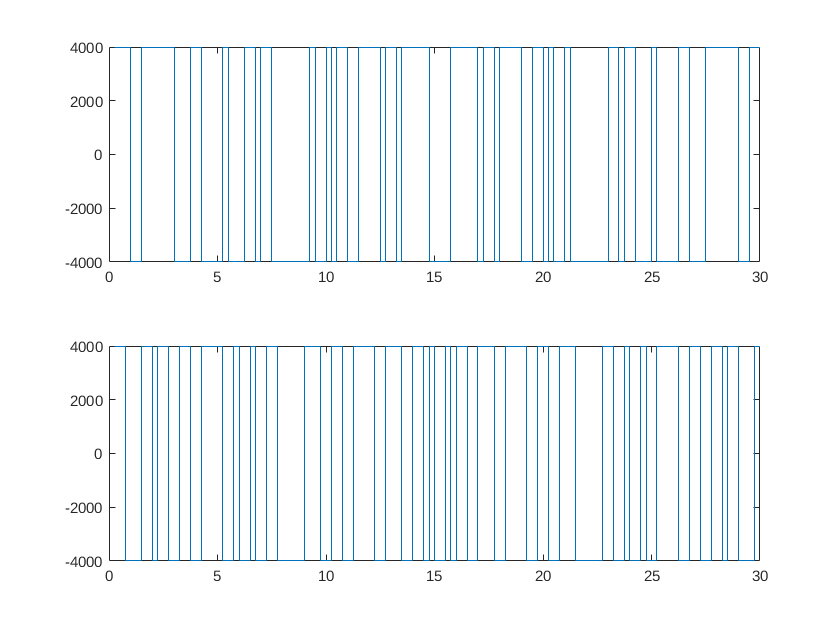


h = 0.25;
N = 120;
Tfinal = N*h;   
uu = idinput(N, 'rbs', [0, 0.8]);
forceMagnitude = 4e3;
u1 = forceMagnitude*uu(1:N/2);
u1v = forceMagnitude*uu(N/2+1:N);
t = (1:N)'*h;
input1 = cat(2, t, cat(1, u1, flipud(u1)));
input1v = cat(2, t, cat(1, u1v, flipud(u1v)));

figure(1)
subplot(211)
stairs(input1(:,1), input1(:,2))
subplot(212)
stairs(input1v(:,1), input1v(:,2))

## Load data

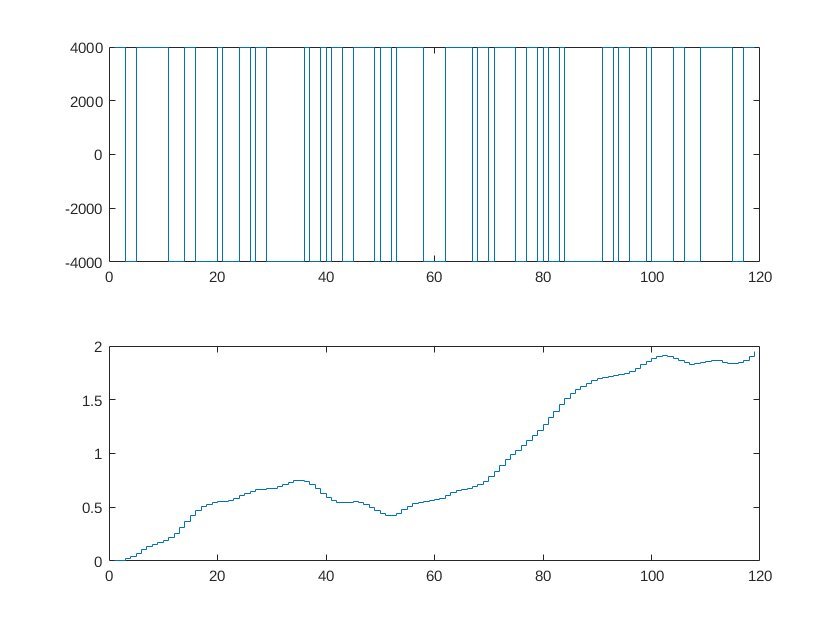

uident = out.simout.Data(3:end,1);
yident = out.simout.Data(3:end,2);
figure()
subplot(211);
stairs(uident)
subplot(212)
stairs(yident)

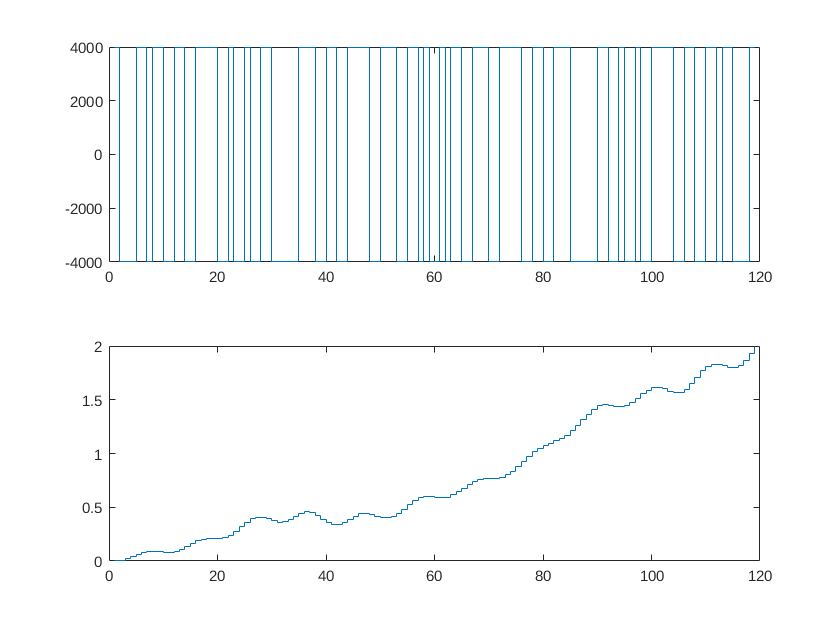



uval = out.simout2.Data(3:end,1);
yval = out.simout2.Data(3:end,2);
figure()
subplot(211);
stairs(uval)
subplot(212)
stairs(yval)

## Estimate models

iddta1 = iddata(yident,uident, h);
valdta1 = iddata(yval, uval, h);

% Second order model, one zero, two poles, one delay
% (b0 z + b1) / (z^2 + a1z + a2)
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.965 z^-1 + 0.9644 z^-2              
                                                   
  B(z) = -2.225e-07 z^-1 - 1.374e-08 z^-2          
                                                   
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 98.72% (prediction focus)
FPE: 6.698e-05, MSE: 6.055e-05                   



% Second order model, one zero, two poles, two delays
% (b0 z + b1) /(z*(z^2 + a1z + a2))
arx222 = arx(iddta1, [2, 2, 2])

arx222 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.966 z^-1 + 0.9654 z^-2              
                                                   
  B(z) = -1.516e-07 z^-2 + 4.507e-07 z^-3          
                                                   
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=2
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 98.74% (prediction focus)
FPE: 6.446e-05, MSE: 5.828e-05                   



% fourth order model, three zeros, four poles, one delay
% (b0 z^3 + b1z^2 + b2z + b3) / (z^4 + a1z^3 + a2z^2 + a3z + a4)
arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                       
  A(z) = 1 - 3.64 z^-1 + 5.255 z^-2 - 3.588 z^-3 + 0.9741 z^-4            
                                                                          
  B(z) = 1.026e-08 z^-1 + 2.693e-07 z^-2 + 2.386e-07 z^-3 - 4.966e-08 z^-4
                                                                          
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.97% (prediction focus)
FPE: 4.991e-08, MSE: 4.077e-08                   



% sixth order model, five zeros, six poles, one delay
arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                         
  A(z) = 1 - 4.506 z^-1 + 9.049 z^-2 - 10.48 z^-3 + 7.453 z^-4 - 3.146 z^-5 + 0.6257 z^-6                   
                                                                                                            
  B(z) = 7.966e-09 z^-1 + 2.671e-07 z^-2 + 1.612e-09 z^-3 - 7.145e-08 z^-4 + 1.675e-07 z^-5 + 2.885e-09 z^-6
                                                                                                            
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.99% (prediction focus)
FPE: 9.176e-09, MSE: 6.765e-09                   



% sixth order model, five zeros, six poles, two delays
arx662 = arx(iddta1, [6, 6, 2])

arx662 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                         
  A(z) = 1 - 4.434 z^-1 + 8.703 z^-2 - 9.783 z^-3 + 6.734 z^-4 - 2.758 z^-5 + 0.5382 z^-6                   
                                                                                                            
  B(z) = 2.687e-07 z^-2 + 1.903e-08 z^-3 - 7.824e-08 z^-4 + 1.439e-07 z^-5 + 6.432e-09 z^-6 + 6.706e-09 z^-7
                                                                                                            
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=2
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.99% (prediction focus)
FPE: 9.803e-09, MSE: 7.227e-09                   



% eigth order model, seven zeros, eight poles, one delay
arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                
  A(z) = 1 - 3.5 z^-1 + 5.126 z^-2 - 4.23 z^-3 + 3.034 z^-4 - 3.325 z^-5 + 3.402 z^-6 - 2.069 z^-7 + 0.5615 z^-8   
                                                                                                                   
                                                                                                                   
  B(z) = 1.068e-08 z^-1 + 2.747e-07 z^-2 + 2.759e-07 z^-3 + 9.012e-08 z^-4 + 6.395e-08 z^-5 + 1.512e-07 z^-6       
                                                                                  + 1.582e-07 z^-7 + 4.859e-09 z^-8
                                                                                                                   
Sample time: 0.25 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters 


% 12th order model, 
arx12121 = arx(iddta1, [12, 12, 1])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                
                                                                                                                   
  A(z) = 1 - 2.126 z^-1 + 1.864 z^-2 - 1.347 z^-3 + 1.164 z^-4 - 0.5688 z^-5 - 0.09494 z^-6 - 0.003329 z^-7        
                                         + 0.04511 z^-8 - 0.05504 z^-9 + 0.3142 z^-10 - 0.5213 z^-11 + 0.3283 z^-12
                                                                                                                   
                                                                                                                   
  B(z) = 8.856e-09 z^-1 + 2.885e-07 z^-2 + 6.686e-07 z^-3 + 9.08e-07 z^-4 + 9.661e-07 z^-5 + 8.403e-07 z^-6        
             + 7.288e-07 z^-7 + 6.19e-07 z^-8 + 4.711e-07 z^-9 + 2.86e-07 z^-10 + 9.612e-08 z^-11 + 2.678e-09 z^-12
                                                             


% Fourth order state space model
ss4 = n4sid(iddta1, 4);

% Sixth order state space model
ss6 = n4sid(iddta1, 6);


## Compare models

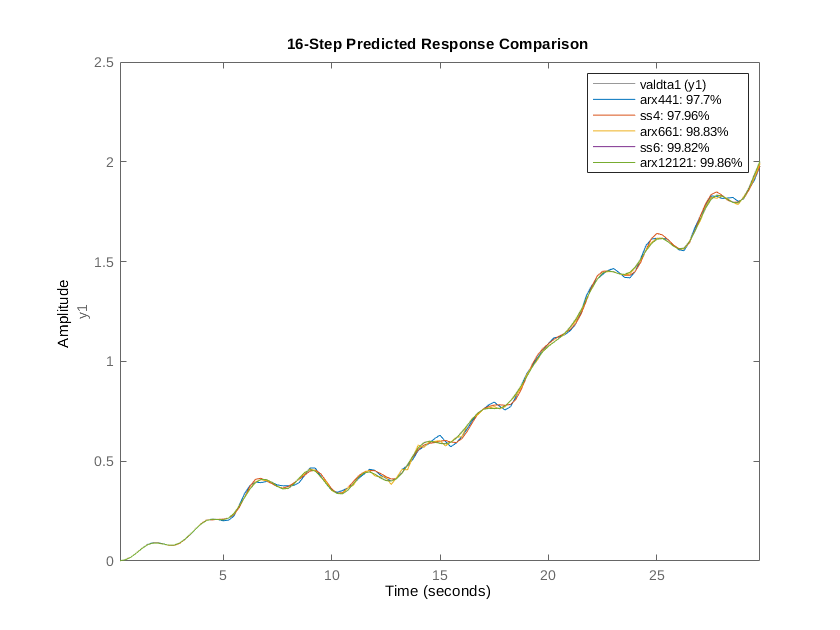

compare(valdta1, arx441, ss4, arx661, ss6, arx12121, 16)

aic(arx441, ss4, arx661, ss6, arx881, arx12121)

Model quality according to the "nAIC" measure:
  -16.8138  -15.1899  -18.5091  -20.4121  -19.6811  -20.9881



## Export models for use in Simulink

[num, den] = tfdata(tf(arx441))

num = 1×1 cell array
    {[0 1.0264e-08 2.6935e-07 2.3865e-07 -4.9656e-08]}


den = 1×1 cell array
    {[1 -3.6405 5.2547 -3.5883 0.9741]}


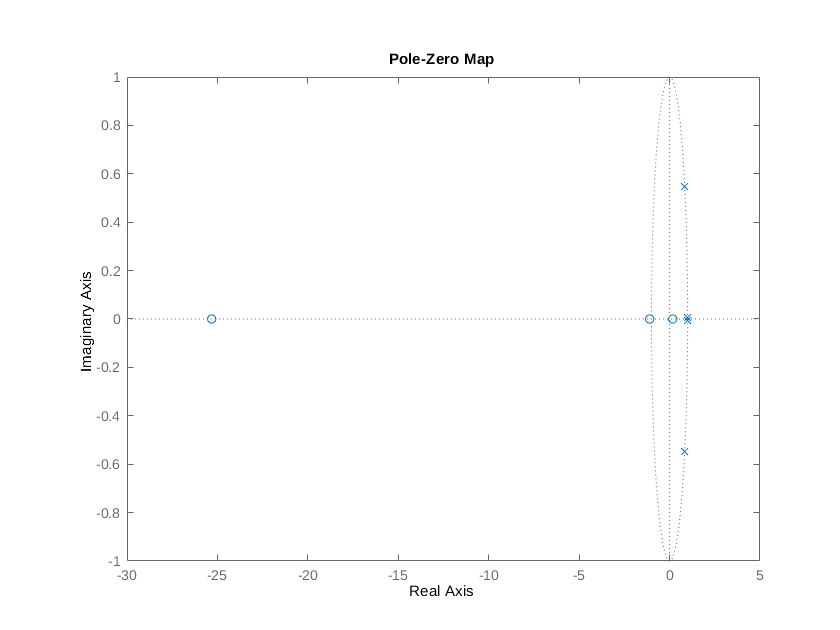

figure()
clf
pzmap(arx441)

save crane_sysid_result.mat arx441 arx661 ss4 ss6
